Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds. Index must not exceed 1.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds. Index must not exceed 1.


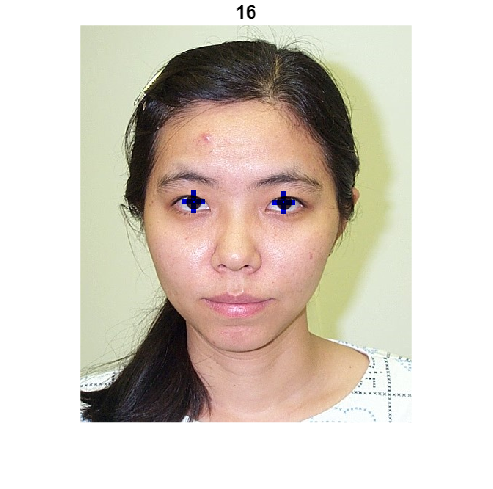

for i =1:16 
    im = im2double(imread("Faces/db1_" + i + ".jpg"));

    [eye1,eye2] = findEyes(im);
    
    imX = showEyes(im, eye1, eye2);
    imshow(imX);title(i)
    pause(0.1)
end

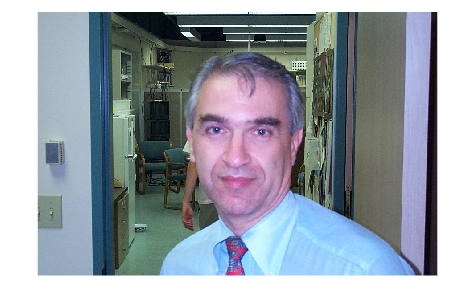

im = im2double(imread("Faces/DB2/bl_" + 4 + ".jpg"));
imshow(im)

[eye1,eye2] = findEyes(im); 

Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.


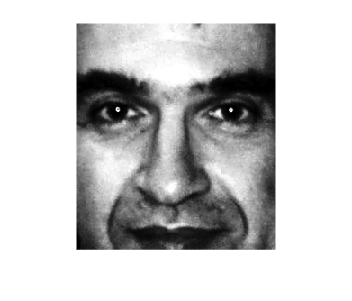

imX = faceNormalization(im, eye1, eye2);
imshow(imX)

for i =1:16 
    im = im2double(imread("Faces/db0_" + 2 + ".jpg"));
    mask = im;
    for j=1:5
        mask = skinMask(mask);
        mask = mask.*im;
    end
    imshow(mask);title(i)
    pause(0.1)
end

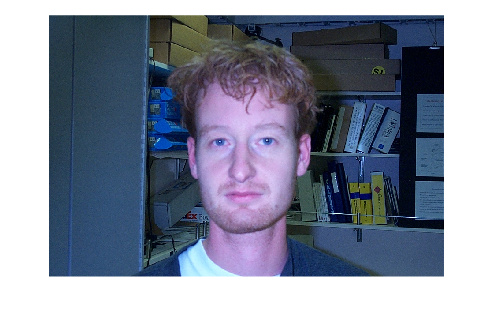

im = im2double(imread("Faces/db2/il_" + 12 + ".jpg"));
faceDetector = vision.CascadeObjectDetector;
bboxes = faceDetector(im);
IFaces = insertObjectAnnotation(im,'rectangle',bboxes,'Face');   
figure
imshow(IFaces)
title('Detected faces');

imIn = im2double(imread("Faces/db2/bl_" + 2 + ".jpg"));

imOut = colorCorrection(imIn)

imOut = imOut(:,:,1) =

    0.1221    0.1064    0.0985    0.1005    0.1044    0.1044    0.1083    0.0945    0.0926    0.1005    0.1083    0.1123    0.1221    0.0847         0         0    0.0098    0.0039    0.0039    0.0118    0.0059         0    0.0039         0    0.0059    0.0098    0.0020    0.0158    0.0295    0.0138    0.0059    0.0020    0.0020    0.0020    0.0020    0.0059    0.0059    0.0059    0.0039    0.0039    0.0039    0.0039    0.0039    0.0020    0.0039    0.0079    0.0059         0    0.0217    0.0098    0.0039         0    0.0039    0.0118    0.0059    0.0020    0.0020    0.0020    0.0098    0.0039    0.0098    0.0138         0    0.0079    0.0098    0.0059    0.0158    0.0079         0    0.0098    0.0098    0.0118    0.0039         0         0    0.0039         0         0         0    0.0039    0.0039         0    0.0079    0.0039    0.0020         0    0.0039    0.0039    0.0039    0.0039    0.0039    0.0098         0         0    0.0059    0.0079    0.0118    0.

figure
%imshow(imOut)

im = im2double(imread("Faces/db2/bl_" + 1 + ".jpg"));
myMask = skinMask(im);

% Get the properties of connected components in the binary image
stats = regionprops(myMask, 'Centroid');

% Extract the centroid coordinates
centroid = stats.Centroid

centroid =   445.0012  310.5823


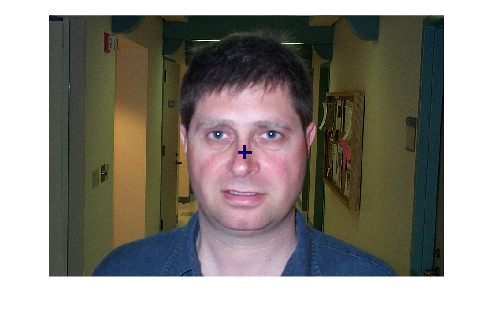

im = drawX(im,centroid(1),centroid(2));
figure
imshow(im)

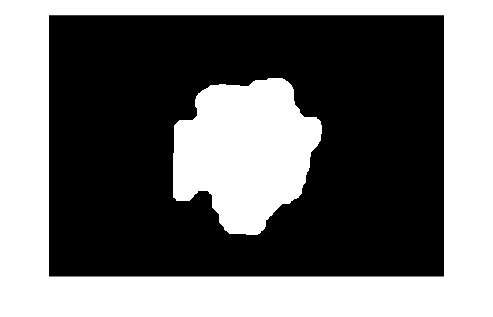

imshow(myMask)


myMask = skinMask(im);

% Get the properties of connected components in the binary image
stats = regionprops(myMask, 'Centroid');

% Extract the centroid coordinates
centroid = stats.Centroid

centroid =   452.6453  338.0237


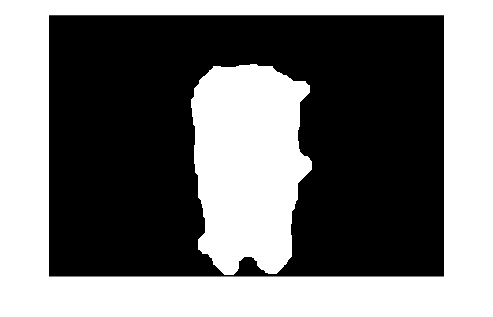

im = drawX(im,centroid(1),centroid(2));

imshow(myMask)

image = im2double(imread("Faces/db2/bl_" + 10 + ".jpg"))

image = image(:,:,1) =

    0.1608    0.1333    0.1333    0.1333    0.1373    0.1294    0.1373    0.1294    0.1255    0.1333    0.1412    0.1373    0.1333    0.1333    0.1451    0.1451    0.1843    0.1529    0.1451    0.1529    0.1529    0.1451    0.1490    0.1529    0.1569    0.1686    0.1804    0.1725    0.1804    0.1765    0.1412    0.1490    0.1490    0.1412    0.1451    0.1569    0.1569    0.1451    0.1373    0.1451    0.1451    0.1490    0.1490    0.1412    0.1686    0.1490    0.1490    0.1373    0.1490    0.1137    0.1176    0.1255    0.1333    0.1412    0.1255    0.0824    0.0627    0.0745    0.1294    0.1529    0.1255    0.1412    0.1725    0.1451    0.1490    0.1490    0.1373    0.1294    0.1686    0.1333    0.1333    0.1176    0.1373    0.1020    0.1373    0.1255    0.1294    0.1333    0.1490    0.1294    0.1294    0.1647    0.1451    0.1412    0.1529    0.1255    0.1255    0.1137    0.1333    0.1098    0.1294    0.1765    0.1529    0.1333    0.1373    0.1176    0.1412    0.


% Specify the illuminant color using illumwhite
illuminantColor = illumwhite(image, 8)

illuminantColor =     0.7059    0.6078    0.8275



% Perform chromatic adaptation
adaptedImage = chromadapt(image, illuminantColor,'ColorSpace', 'srgb');

adaptedImage = adaptedImage(:,:,1) =

    0.1119    0.0858    0.0825    0.0828    0.0888    0.0812    0.0847    0.0769    0.0704    0.0784    0.0902    0.0863    0.0825    0.0825    0.0993    0.1025    0.1416    0.1127    0.1053    0.1079    0.1044    0.0948    0.1021    0.1058    0.1144    0.1251    0.1387    0.1299    0.1343    0.1322    0.0966    0.1040    0.1040    0.0946    0.1005    0.1116    0.1117    0.1006    0.0932    0.1006    0.1005    0.1042    0.1043    0.0969    0.1227    0.1042    0.1040    0.0894    0.1009    0.0601    0.0608    0.0689    0.0834    0.0946    0.0850    0.0472    0.0311    0.0380    0.0843    0.1013    0.0716    0.0908    0.1315    0.1062    0.1098    0.1067    0.0885    0.0811    0.1281    0.0957    0.0955    0.0773    0.0894    0.0477    0.0916    0.0819    0.0885    0.0935    0.1098    0.0885    0.0885    0.1168    0.1030    0.0993    0.1087    0.0772    0.0729    0.0563    0.0769    0.0595    0.0833    0.1324    0.1103    0.0902    0.0885    0.0693  

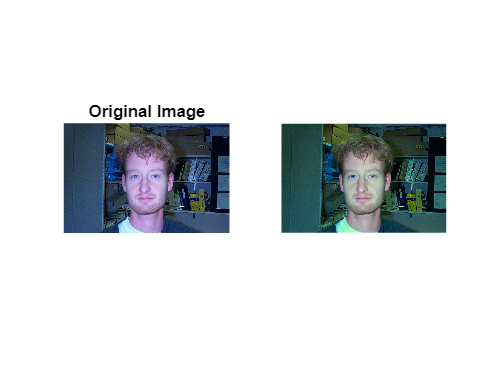

imshow(adaptedImage)

idArray = [1,2,4,5,6,7,10,13,14];
%idArray=[13]
path = "Faces/db2/cl_5";

for i=1:length(idArray)
    im = im2double(imread(path + ".jpg"));

    maskSkin = skinMask2(im);
    maskThreshold = thresholdMask(im);
    maskSobel = sobelMask(im);
    SE = strel('disk', 4);
    maskSobel = imclose(maskSobel, SE);
    
    % Combine face masks using logical AND and OR operations
    maskA = maskSkin; %.* maskThreshold;
    maskB = maskThreshold .* maskSobel;
    maskC = maskSkin .* maskSobel;
    mask = maskA | maskB | maskC;
    mask = imfill(mask, 'holes');
    mask = violaJones(double(mask).*im);
    imshow(double(mask).*im)
    pause(0.1)
end    

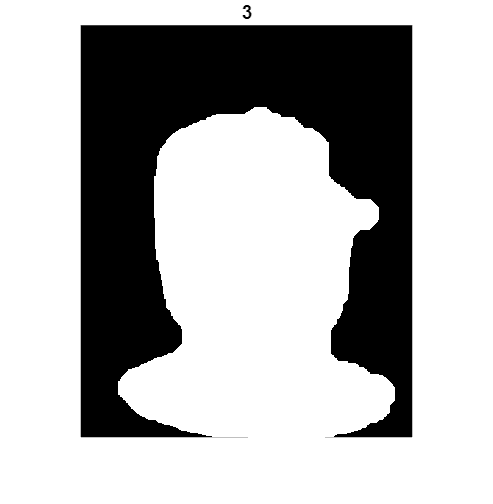

% Load face images from a folder
imageDir = 'Faces/';
imageDir2 = 'Faces/DB2/';
testimages = dir(fullfile(imageDir, '*.jpg'));
testimages2 = dir(fullfile(imageDir2, '*.jpg'));
allImages = [testimages; testimages2];
numImages = numel(allImages);

% Read images into a cell array
faceData = cell(1, numImages);
for i = 1:numImages
    % Load your image
    im = imread(fullfile(allImages(i).folder, allImages(i).name));
    im = skinMask(im);  
    imshow(im);title(i)
    pause(0.1)
end

imIn = im2double(imread("Faces/DB2/il_7" + ".jpg"));
faceDetector = vision.CascadeObjectDetector('EyePairBig');
bbox = faceDetector(imIn)

bbox =    337   235   231    57


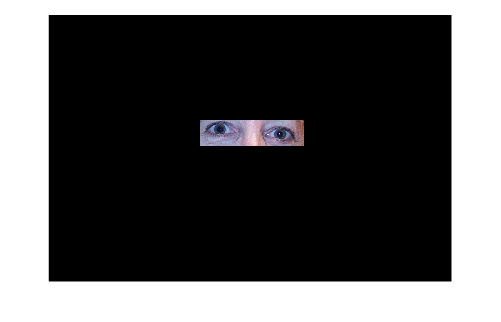

n1 = bbox(1);
n2 = bbox(1)+bbox(3);
m1 = bbox(2);
m2 = bbox(2)+bbox(4);


binaryMask = zeros(size(imIn, 1), size(imIn, 2));
binaryMask(m1:m2, n1:n2) = 1;

imshow(binaryMask.*imIn)

Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.


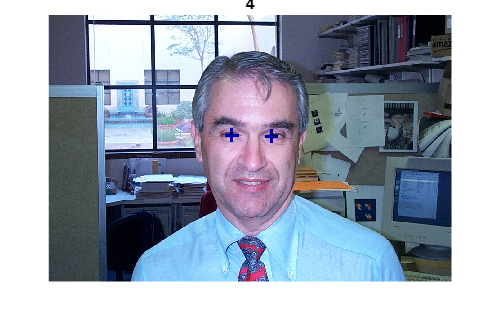

Error using imread>get_full_filename
File "Faces/db2/ex_5.jpg" does not exist.

Error in imread (line 372)
        fullname = get_full_filename(filename);

idArrayCL = [1,2,4,5,6,7,10,13,14];% done
idArrayBL = [1 2 4 5 6 7 10 13 14];% done
idArrayIL = [1 7 8 9 12 16];
idArrayEX = [1 3 4 9 11 12];
% ERROR at: il_7 il_16
path = "Faces/db2/ex_";
idArray = idArrayEX;

for i=1:length(idArray)
    im = im2double(imread(path + idArray(i) +".jpg"));

    [eye1,eye2] = findEyes(im);
    
    imX = showEyes(im, eye1, eye2);
    imshow(imX);title(idArray(i))    
    pause(0.1)
end 

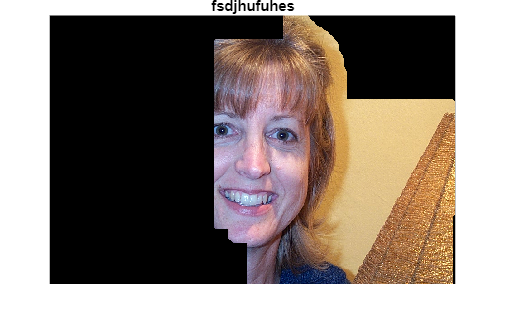

path = "Faces/db2/il_7";

imIn = im2double(imread(path + ".jpg"));
mask = skinMask2(adjustRGB(imIn));
%mask = violaJones(imIn);

imshow(mask.*imIn); title('fsdjhufuhes')

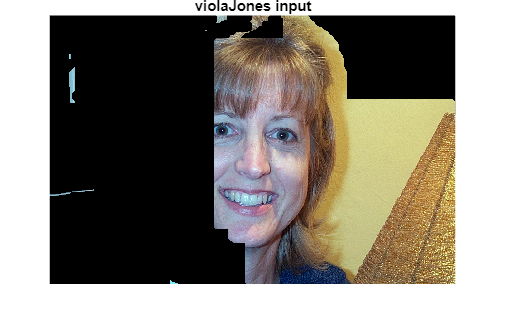

Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.


path = "Faces/db2/il_7";
% ERROR at: il_7 (mask2 don capture eyes)

imIn = im2double(imread(path + ".jpg"));
[eye1,eye2] = findEyes(adjustRGB(imIn));

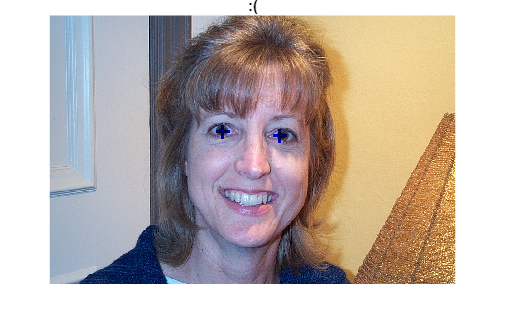

    
imX = showEyes(imIn, eye1, eye2);
imshow(imX);title(':(')  